# Project Sysyphus [Sizing cosntraint]  

## Var

clear
%Design variable
    wingSpan = 5.6; % [m] Denoted as 'b' sometimes 
    AR = 18.5; %[m] 
    mBat = 2.9; %[kg]
%Performance metrics 
    excessTime = 200; % [h] Aircraft edurance 
    chargeMargin = 200; % ?? wtf is this 
%User input
    payloadMass = 200; % [kg] Payload Mass 
    altitudeReq = 200; % [m] Altitude requirement
    latitudeReq = 200; % [m] Bruh
    timeReq = 18; % [h] Time requirement  


Finding plane's total energy. Neglecting kinetic energy by applying quasi-state energy assumption

 
$${\textrm{Energy}}_{\textrm{Input}\;} ={\textrm{Energy}}_{\textrm{Output}}$$


### **Finding eletric energy **

%Electric energy      
    pBat = 1500; % [W] Assumed Total battery power output
    muBat = 0.2; % [-] Assumed Battery effifency, respect with charge and discharge losses 
    pSolar = 1500; % [W] Assumed Solar power input 
    pOut = 1400; % [W] Assumed Battery power output 
%{Electric charge rate There are different charge rate in terms of how
% charge the battery is, below shows the 3 conditions on different charge
%rate}
    eBat = 251; % [Wh/kg] Battery energy 
    f_frc = 1.4; % [-] Charge/Discharge ratio 
    pChargeTotaLimit = eBat *f_frc; % [-] Total charge limit
    sigmaBattery = 1; % [-] Assumed battery charge ratio
    sigmaBatteryExponetialChargeLimit = 0.9; % [-] Assumed battery charge decay limit 
    c1 = 1; % [-] Discharge rate loss constant 
    if sigmaBattery >= 1
        pChargeRate = 0; % [mAh] battery charge rate = 0 as battery is already full (1)
    elseif sigmaBattery > sigmaBatteryExponetialChargeLimit 
        pChargeRate = exp(-c1*((sigmaBattery-sigmaBatteryExponetialChargeLimit)/(1-sigmaBatteryExponetialChargeLimit))*pChargeTotalLimit);
    else
        min(pSolar-pOut, pChargeTotaLimit);
    end
    



Prop information from APC website 

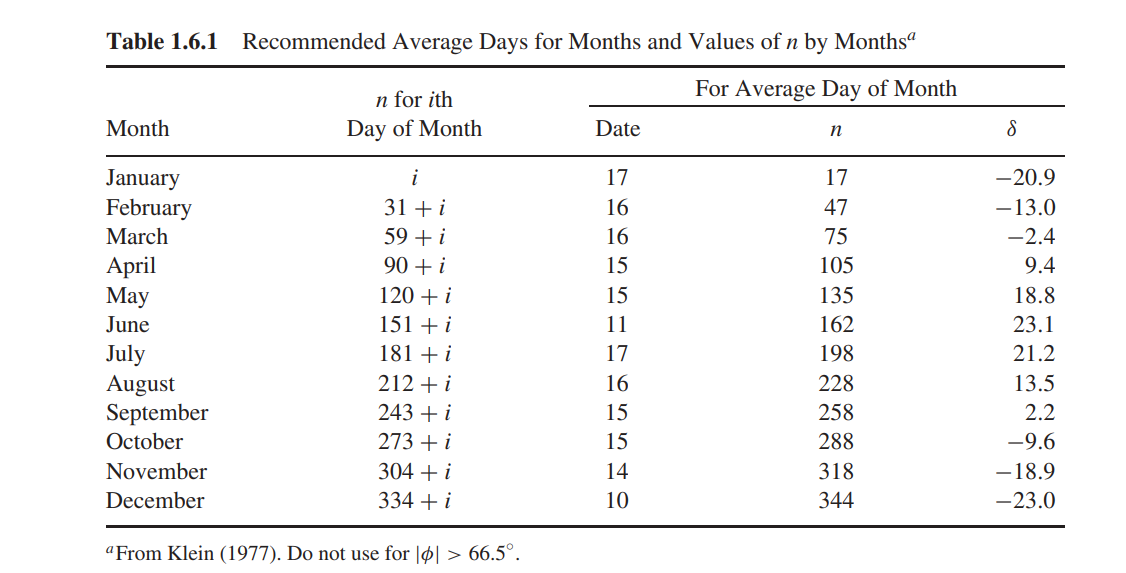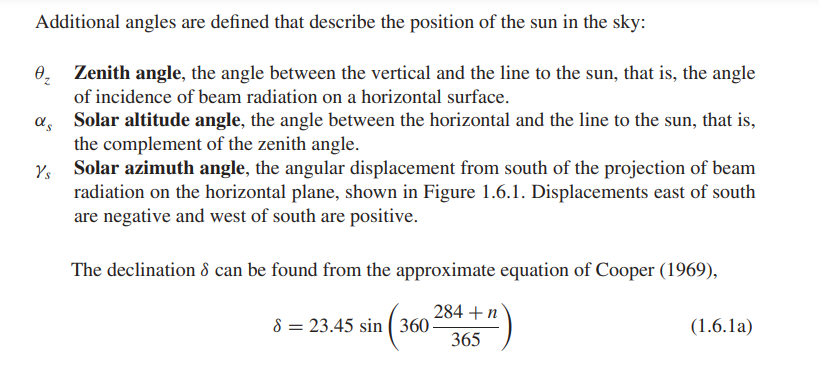

latitude = 53.4808; % [deg] manchester latitude 
G_sc = 1367;
n = 162; %June n value
G_sc = 

Isolar = (((12*3600*G_sc)/pi)*(1+0.033*cos(360*n/365)))*(cos(phi)*cos(delta)*(sin(omega_2)-sin(omega_1))...
    +((pi*(omega_2-omega_1)/180))*sin(phi)*sin(delta));


%propInformation = readtable("C:\Users\Matthew\Downloads\DAIKO_trajectory_v2.csv"); 
%Assumed velocity is 
